%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on DNA/DNA TMSD kinetics 

b = 20 %define branch migration domain length 

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold lengths 
for g = 1:15
%    dGboxA = 0
%    dGboxB1 = dGassoc + dGvol + dGbp
%    dGboxC1 = dGassoc + dGvol + dGbp*g
%    dGboxCrD = dGassoc + dGvol + dGbp*g + dGp
%    dGboxE = dGboxCrD - dGassoc - dGvol
%    dGboxF = dGboxE + dGbp

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
    else
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    end
    
    Pn_j0 = zeros(1,numel(Kf))
    Pn_j0 (1) = 0
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_j0(Pn)  = 1/Kf(Pn) + Kb(Pn-1)/Kf(Pn)*Pn_j0(Pn-1)
    end

    first_pass_time (g) = sum(Pn_j0) %calculate first passage time 
    k_eff (g) = 1/(first_pass_time (g)*(5*10^-8)) %calculate effective rate constant
    prob_unbound(g) = Pn_j0(end)/sum(Pn_j0) %calculate probability of being in unbound state
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb = 	1.0e+07 *

         0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0


Pn_j0 = 	1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.8046


first_pass_time = 	1.0e+05 *

    4.8046         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =    41.6271         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.8662


first_pass_time =     4.8046    0.3866         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =    41.6271  517.2996         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.1157


first_pass_time =     4.8046    0.3866    0.0312         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0416    0.5173    6.4190         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000  255.6777


first_pass_time =     4.8046    0.3866    0.0312    0.0026         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0042    0.0517    0.6419    7.8214         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000   25.5583


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0004    0.0052    0.0642    0.7821    7.8161         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    7.0430


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001         0         0         0         0         0         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    5.5532


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001         0         0         0         0         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    5.4334


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001         0         0         0         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    1.0000


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.4237


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678    3.6679         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945    0.9945         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678    3.6679    3.6679         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945    0.9945    0.9945         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678    3.6679    3.6679    3.6679         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678    3.6679    3.6679    3.6679    3.6679         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.6059    0.9089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3938    0.4241    0.4544    0.4847    0.5150    0.5453    0.5756         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0222    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     4.8046    0.3866    0.0312    0.0026    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


k_eff =     0.0000    0.0005    0.0064    0.0782    0.7816    2.8277    3.5822    3.6608    3.6673    3.6678    3.6679    3.6679    3.6679    3.6679    3.6679


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9958    0.9946    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945


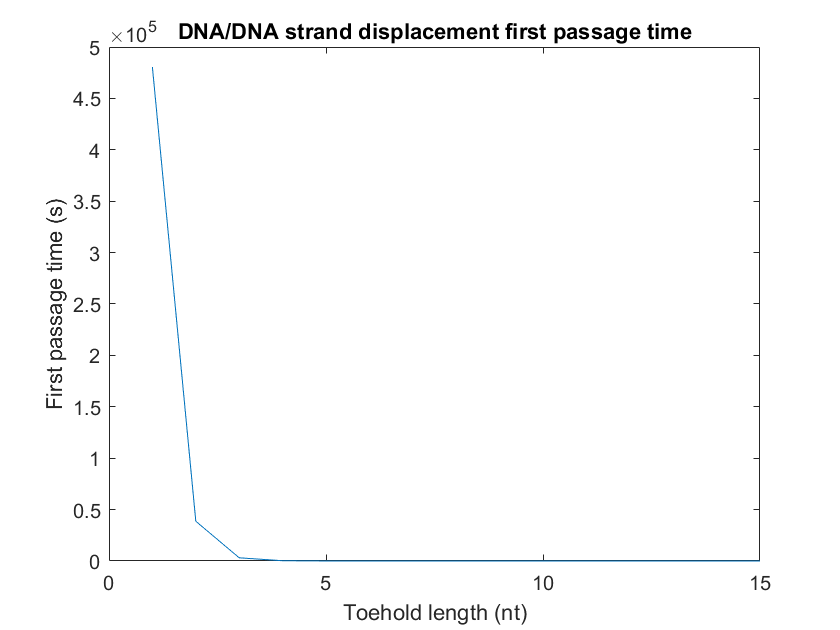

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

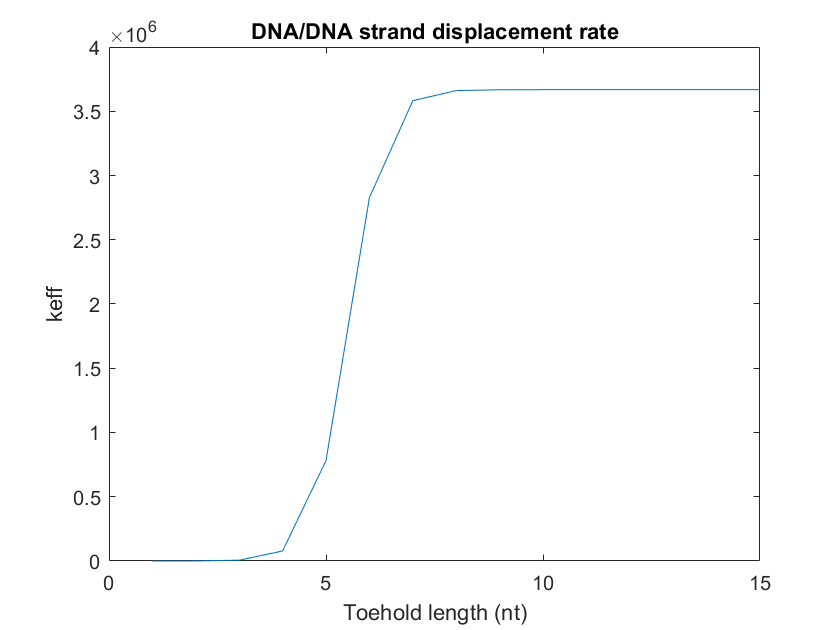


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

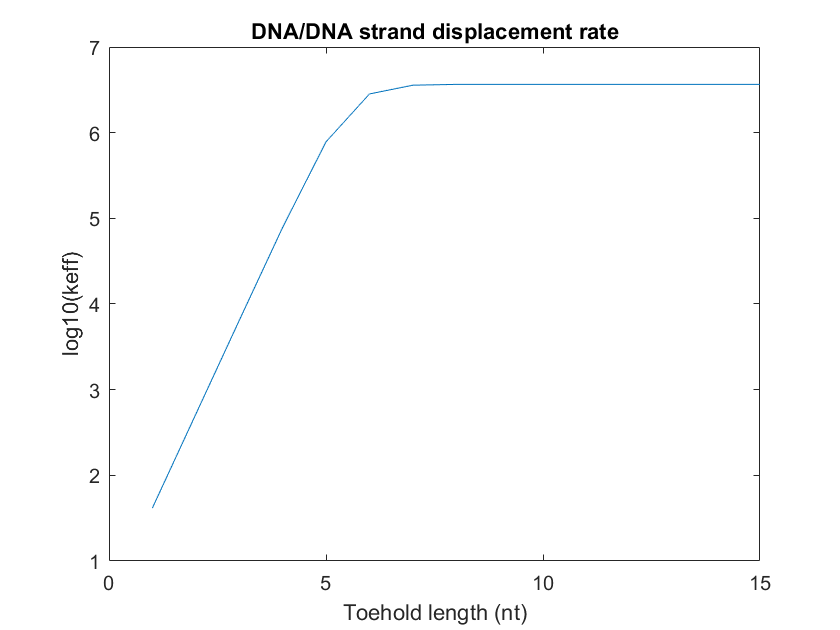


plot(1:15, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  